# Estimate Robot Position in a Loop Using Particle Filter

Use the `stateEstimatorPF` object to track a robot as it moves in a 2-D space. The measured position has random noise added. Using `predict` and `correct`, track the robot based on the measurement and on an assumed motion model.

Initialize the particle filter and specify the default state transition function, the measurement likelihood function, and the resampling policy.

pf = stateEstimatorPF;
pf.StateEstimationMethod = 'mean';
pf.ResamplingMethod = 'systematic';

Sample 1000 particles with an initial position of [0 0] and unit covariance.

initialize(pf,1000,[0 0],eye(2));

Prior to estimation, define a sine wave path for the dot to follow. Create an array to store the predicted and estimated position. Define the amplitude of noise.

t = 0:0.1:4*pi;
dot = [t; sin(t)]';
robotPred = zeros(length(t),2);
robotCorrected = zeros(length(t),2);
noise = 0.1;

Begin the loop for predicting and correcting the estimated position based on measurements. The resampling of particles occurs based on the`ResamplingPolicy` property. The robot moves based on a sine wave function with random noise added to the measurement.

for i = 1:length(t)
    % Predict next position. Resample particles if necessary.
    [robotPred(i,:),robotCov] = predict(pf);
    % Generate dot measurement with random noise. This is
    % equivalent to the observation step.
    measurement(i,:) = dot(i,:) + noise*(rand([1 2])-noise/2);
    % Correct position based on the given measurement to get best estimation.
    % Actual dot position is not used. Store corrected position in data array.
    [robotCorrected(i,:),robotCov] = correct(pf,measurement(i,:));
end

Plot the actual path versus the estimated position. Actual results may vary due to the randomness of particle distributions.

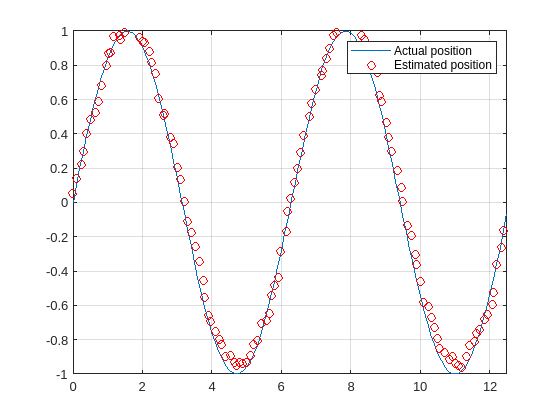

plot(dot(:,1),dot(:,2),robotCorrected(:,1),robotCorrected(:,2),'or')
xlim([0 t(end)])
ylim([-1 1])
legend('Actual position','Estimated position')
grid on

The figure shows how close the estimate state matches the actual position of the robot. Try tuning the number of particles or specifying a different initial position and covariance to see how it affects tracking over time.

*Copyright 2019 The MathWorks, Inc.*